Importing the data from Excel 

data = readmatrix('Winter.xlsx')

data =            1        1001         935
           2         967         923
           3         946         918
           4         939         931
           5         934         976
           6         952        1026
           7        1004        1167
           8        1095        1319
           9        1206        1327
          10        1276        1284


Inputs = data(:,1:2);
Target = data(:,3);

 Visulisation of Input and Target Load Data

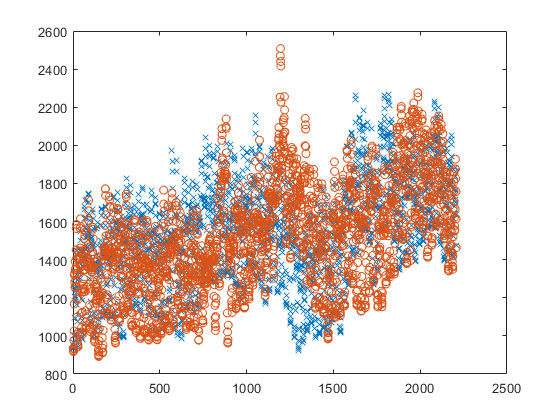

plot(Inputs(:,2),'x')
hold on
plot(Target,'o')
hold off

Training the Artificial Neural Netwok ANN

Xt = Inputs';    %Transpose of input data
Yt = Target';    %Transpose of traget data
hiddenLayerSize = [70 40];   % number of neurons in each of two hidden layer
net = fitnet(hiddenLayerSize); % network builder

Dividing the data of Inputs and Target according to the Train data, Validation data and Test data.

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainFcn = 'trainbr' %Bayesian Regularization command

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2910
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

[net,tr] = train(net,Xt,Yt)

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3091
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

tr = struct with fields:
        trainFcn: 'trainbr'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×1877 double]
          valInd: []
         testInd: [1×331 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 1000
       trainMask: {[1×2208 double]}
         valMask: {[1×2208 double]}
        testMask: {[1×2208 double]}
      best_epoch: 1000
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'gamk'  'ssX'  'val_fail'}
           epoch: [1×1001 double]
            time: [1×1001 double]
            perf: [1×1001 double]
           vperf: [1×1001 double]
           tperf: [1×1001 double]
              mu: [1×1001 double]
        gradient: [1×1001 double]
            gamk: [1×1001 double]
             ssX: [1×1001 double]
        val_fail: [1×

Performance of the ANN


yTrain = net(Xt(:,tr.trainInd)); 
yTrainTrue = (Yt(tr.trainInd));
RMSE1=(sqrt(mean((yTrain-yTrainTrue).^2)))

RMSE1 = 26.9496


yval = net(Xt(:,tr.valInd)); 
yvalTrue = (Yt(tr.valInd));
RMSE2=sqrt(mean((yval-yvalTrue).^2))

RMSE2 = NaN


yTest = net(Xt(:,tr.testInd)); 
yTestTrue = (Yt(tr.testInd));
RMSE3=sqrt(mean((yTest-yTestTrue).^2))

RMSE3 = 216.4397

E = yTrainTrue - yTrain

E =   -82.1079   -3.8819  -37.1825   16.0475   47.7847  102.2109   -4.1435  -11.4009    7.1435  -47.1702   32.3932   54.4743   13.0367   -1.8088  -38.3000    2.5087   39.9579    0.4252  -72.4895   -1.1241  -15.3353  -38.4617    8.8744   12.2589  -16.1110   12.8877   38.2736   24.2889  -20.5811    3.7682  -34.5357    5.9864   18.5633  -42.2170  -33.7998    0.2312   -0.4153   33.5082   41.7738  -15.5097  -13.3322  -24.2567   17.3403    0.5456    1.7002    7.4972    7.5477    5.0900   18.5184    2.2150


MAE = mae(E)

MAE = 17.6062

MAPE= mean((abs(yTrain-yTrainTrue))./yTrainTrue)

MAPE = 0.0121

MSE = mse(net,yTrainTrue,yTrain)

MSE = 726.2786

Perf = perform(net,yTrain,yTrainTrue)

Perf = 726.2786

Plots

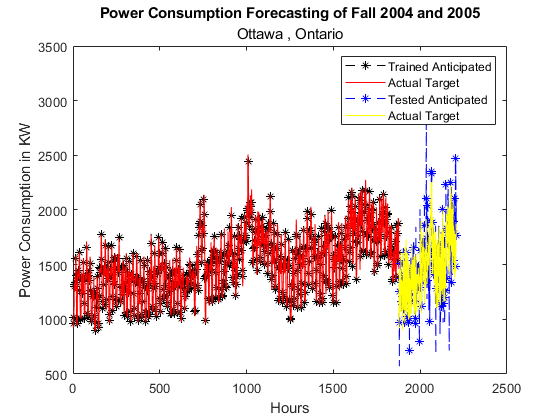

plot(1:1877,yTrain,'k--*',1:1877,yTrainTrue,'r','LineWidth',0.5,'MarkerIndices',1:3:length(yTrainTrue))

title('Power Consumption Forecasting of Fall 2004 and 2005')
subtitle('Ottawa , Ontario')
xlabel('Hours')
ylabel('Power Consumption in KW')
hold on

plot(1878:2208,yTest,'b--*',1878:2208,yTestTrue,'y','LineWidth',0.5,'MarkerIndices',1:3:length(yTestTrue))
legend('Trained Anticipated','Actual Target','Tested Anticipated','Actual Target')
hold off